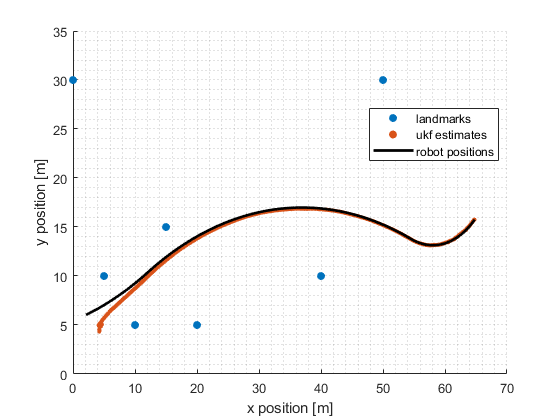

clear variables; close all;clc
% unscented kalman filter example 6
% tracking of a robot
% states = (position x, position y, orientation theta) = (x, y, theta)'
% control inputs = (commanded velocity, steering angle) =  (v, alpha)'

addpath('../utilities');

% time step [s]
dt = 0.1;

% number of input commands
n = 600;

% landmarks information
landmarks = [5 10; 10 5; 15 15; 20 5; 0 30; 50 30; 40 10]';

% dimensions
dim_x = 3;
dim_z = 2 * size(landmarks, 2);
dim_u = 2;

% input commands information
u = ones(dim_u, n);
u(:, 1:100) = u(:, 1:100).*[1.1 0.01]';
u(:, 101:500) = u(:, 101:500).*[1.1 -0.01]';
u(:, 501:600) = u(:, 501:600).*[1.1 0.05]';

% robot information
wheelbase = 0.5;
robot_pos = [2, 6, 0.3]';

% sensor information
range_std = 2;
bearing_std = 3;

% initial condition
% mean
x =  [4, 4, 0.3]';
% covariance
P = diag([0.1 0.1 0.05]);

% process noise covariance
Q = eye(3)*0.0001;

% measure noise covariance
diag_values = repmat([range_std^2 bearing_std^2], 1, size(landmarks, 2));
R = diag(diag_values);
  
% (non linear) state transition function
f = @(x, u, dt, wheelbase) robot_move(x, u, dt, wheelbase);

% Linearized state transition function
F = @(x, u, dt, wheelbase) robot_move_jacob(x, u, dt, wheelbase);

% (non linear) measurement function
h = @(x, landmarks) h_robot(x, landmarks);

% Linearized measurement function
H = @(x, landmarks) h_robot_jacob(x, landmarks);

% data structures
track = zeros(dim_x, n);
x_posterior = zeros(dim_x, n);
P_posterior = cell(1, n);
x_posterior_mat = zeros(dim_x, n);
P_posterior_mat = cell(1, n);

% define weighted mean angle function
wma = @(angles, weights) atan2(sin(angles) * weights', cos(angles) * weights');
    
% filtering
for ii = 1:n    
    % simulate new robot position (x, y, theta)
    robot_pos = robot_move(robot_pos, u(:, ii), dt, wheelbase);
        
    % build observations/measures
    z = robot_measure(robot_pos, landmarks, range_std, bearing_std, dim_z);
    
    % predict
    F = ;
    x = f(x, u, dt, wheelbase);
    P = F*P*F' + Q;
    
    % matlab predict
    [xpred, Ppred] = predict(ekf, dt);

    % update
    % innovation: z - H*x
    % P = P - K*H*P;
    % Joseph equation to reduce numeric errors
    H = h_radar_jacob(x);
    K = P*H' / (H*P*H' + R);
    e = z - h_robot(x, landmarks);
    x = x + K*e;
    P = (eye(dim_x)-K*H)*P*(eye(dim_x)-K*H)' + K*R*K';
    
    % matlab update
    [xcorr, Pcorr] = correct(ekf, z);
   
    % saving
    track(:, ii) = robot_pos;
    x_posterior(:, ii) = x;
    P_posterior{ii} = P;
    x_posterior_mat(:, ii) = xcorr;
    P_posterior_mat{ii} = Pcorr;   
end

% plots
mP_posterior = cell2mat(P_posterior);
cols = 1:size(mP_posterior, 2);
cols = cols(mod(cols,3) ~= 0);
prob = normcdf(6)-normcdf(-6);

figure
hold on; grid minor;
scatter(landmarks(1, :), landmarks(2, :), 'filled');
scatter(x_posterior(1, :), x_posterior(2, :), 10, 'filled');
plot(track(1, :), track(2, :), 'k', 'LineWidth', 2);
% for ii = 1:10:n
%     [h, hc] = plot_covariance_ellipse(x_posterior(1:2, ii), mP_posterior(1:2, cols(2*ii-1:2*ii)), prob);
%     h.set('Color', 'r');
%     hc.set('Color', 'r')
% end
xlabel('x position [m]');
ylabel('y position [m]')
xlim([0 70])
ylim([0 35])
legend('landmarks', 'ukf estimates', 'robot positions', 'location', 'best')